spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/с
nObs = size(spectra, 1);
nStars = size(starNames, 1);
lambdaEnd = lambdaStart + (nObs - 1)*lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';
speed = ones(7, 1);
fg = figure;
set(fg, 'Visible', 'on')
index = zeros(1, nStars);
k = 1;

for i = 1 : 1 : nStars
    s = spectra(:, i);
    [sHa, idx] = min(s);
    lambdaHa = lambda(idx);
    z = (lambdaHa / lambdaPr) - 1;
    speed(i, 1) = z * speedOfLight;
    if speed(i, 1) < 0
        plot(lambda, s, "--", 'LineWidth', 1)
    else
        plot(lambda, s, 'LineWidth', 3)
        index(1, k) = i;
        k = k + 1;
    end
    xlabel('Длина волны, нм')
    ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
    title('Спектры звезд')
    legend(starNames)
    grid on
    hold on
end

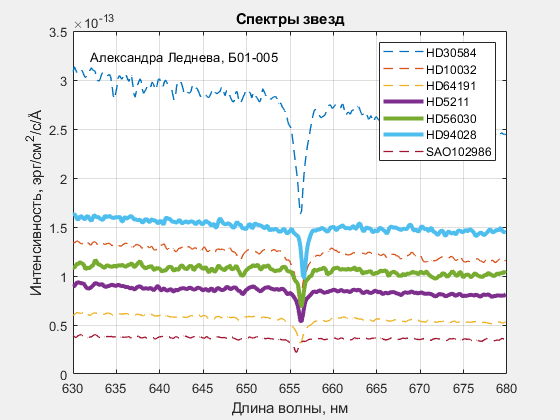


text(632, 3.25*10^(-13), 'Александра Леднева, Б01-005')
saveas(fg, 'spectra.png')

movaway = starNames(index(index(1:1:nStars) > 0), 1)'

movaway = 1×3 cell array
    {'HD5211'}    {'HD56030'}    {'HD94028'}
